FCD_rootdir = 'F:\Dataset\Brain\zysFCD\Group1\';
sub_dirs = dir(FCD_rootdir); sub_dirs(1:2) = [];
sub_dirs = sub_dirs([sub_dirs.isdir]);
sub_num = length(sub_dirs);

# Fig1: cortex attaching to edge

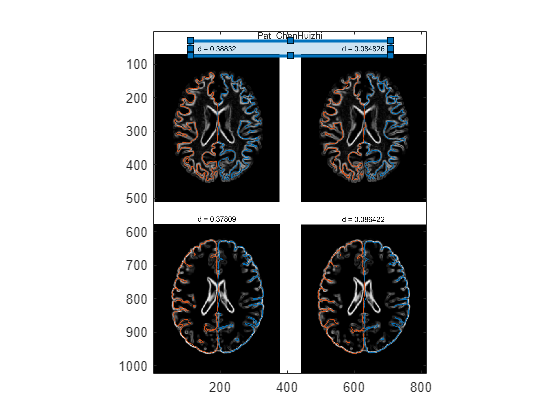

d = 0.38832 d = 0.084826


d = 0.37809 d = 0.086422


d= 0.34017 d= 0.089158


d= 0.38733 d = 0.10527


d= 0.36961 d =0.081379


d=0.35185 d= 0.092316


d = 0.39546 d = 0.10564


d =0.37691 d = 0.099397


d= 0.36789 d =0.079451


d= 0.3991 d = 0.084903


d = 0.39633 d= 0.091384


d=0.35718 d = 0.078906


d=0.37121 d= 0.07384


d= 0.38677 d = 0.085532


d = 0.40882 d = 0.096246


d = 0.38443 d = 0.083336


d= 0.38477 d =0.082781


d= 0.38792 d= 0.081863


d = 0.37965 d = 0.085252


d= 0.35322 d = 0.077652


d= 0.37352 d = 0.084426


d = 0.37244 d = 0.088497


d=0.3521 d = 0.083883


d=0.38017 d=0.10194


d=0.3748 d=0.083138


d = 0.33682 d=0.081921


d= 0.37983 d =0.083781


d = 0.35633 d = 0.08651


d= 0.39481 d = 0.088402


d= 0.40779 d = 0.10807


d = 0.38543 d=0.10277


d = 0.41445 d = 0.091585


d= 0.35861 d= 0.07263


d = 0.38356 d = 0.088942


d =0.38881 d = 0.083547


d = 0.37526 d = 0.085733


d = 0.39652 d = 0.098578


d = 0.39422 d = 0.092555


d = 0.34702 d=0.083513


d= 0.34621 d = 0.086271


ocr_roi1 = [110 30 600 45];
ocr_roi2 = [110 538 600 45];

ii = 1;
for i = 1:20
    try
        subj_dir = [FCD_rootdir,sub_dirs(i).name];
        img = imread([subj_dir,'\surf\surfs_attach.png']);

        if ii==1
            figure;
            showc(img); hold on; drawrectangle('Position',ocr_roi1);
        end

        numbers = getFloat_byOCR(img,ocr_roi1,1);
        d1_init(i) = numbers(1); d1_end(i) = numbers(2);

        numbers = getFloat_byOCR(img,ocr_roi2,1);
        d2_init(i) = numbers(1); d2_end(i) = numbers(2);
        
        ii = ii+1;
    end
end

figure
next; boxplot([d1_init; d1_end]'); yticks([0.1:0.1:0.4])

next; boxplot([d2_init; d2_end]'); yticks([0.1:0.1:0.4])

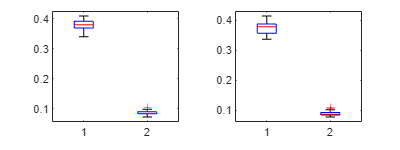

lay_fig([4,1.5])

compare_dir = 'D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig4\compare_reg\';
sMov = MRI_read_Data([compare_dir,'mni.norm.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


sFix = MRI_read_Data([compare_dir,'T1.norm_reg.nii.gz']);

sMRI [229,193,193] res:[1,1,1]



sMov.data = 100*mat_cut(3*sMov.data-1);
sFix.data = 100*sFix.data;


tic
[sReg,trans_params,def_field] = MRI_register(sMov,sFix,'reg_type','nonrigid', ...
    'remake_sz',1,'auto_params',30,'get_field',1,'warp_byField',0);

    FinalGridSpacingInPhysicalUnits: [7 7 7]
                   SampleRegionSize: [7 7 7]
                  ResultImageFormat: 'nii.gz'

    1: E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid3D-OpenCL.txt    

    {'E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\elastix\elastix'                        }
    {'f "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\fix.nii.gz"'                  }
    {'m "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\Images\mov.nii.gz"'                  }
    {'out E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\RegResult'                           }
    {'p "E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\Parameter\para-Nonrigid3D-OpenCL.txt"'}

 
elastix is started at Mon Sep  9 22:02:18 2024. 
 
which elastix:   E:\work_Code\Matlab\ZYS\DIY_App\Elastix_toolbox\\elastix\elastix 
elastix runs at: ZYS2021 
  Windows  Professio

disp_toc

  |->  using 57.9s [==============================================] 2024-09-09 22:03:15


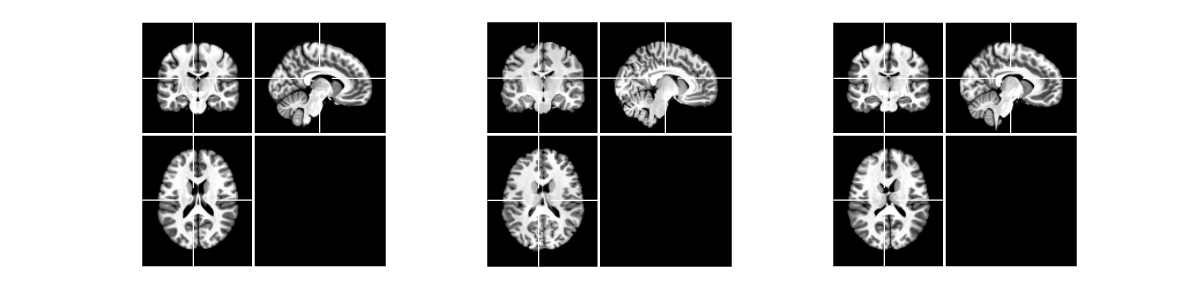


sReg.data = 0.01*single(sReg.data);
figure;
next; plot_mri({sMov,sFix,sReg},'off','enhance',@amp); lay_fig([12,3])

MRI_save_File(sReg.data,['D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig4\compare_reg\T1_elasReg.nii.gz'],'info',sFix);

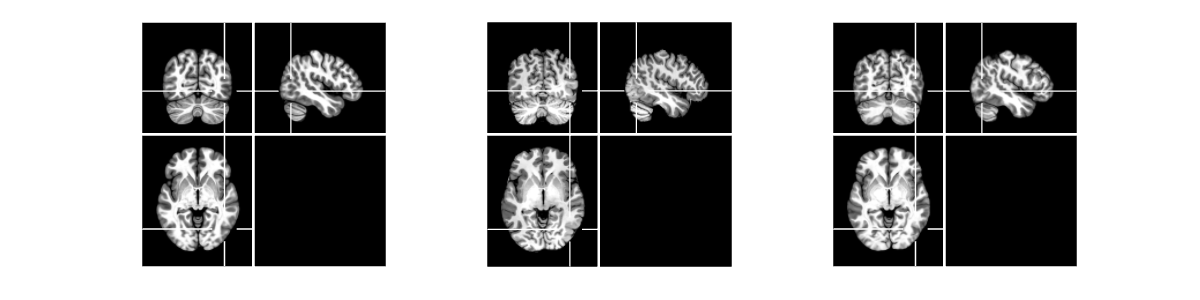

[sReg,~,def_field] = MRI_register(sMov,sFix,'demons','iter',100,'lv',5,'smooth_lv',0.8);
sReg.data = 0.01*single(sReg.data);

figure;
next; plot_mri({sMov,sFix,sReg},'off','pos',pos,'enhance',@amp); lay_fig([12,3])

def_field_demons = def_field;
sWarp = MRI_warp(def_field,sMov,'BST');

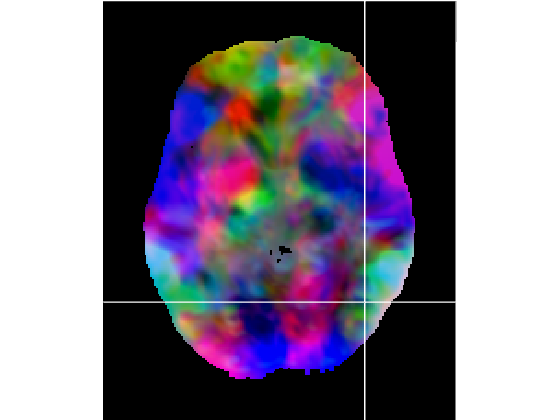

def_field = def_field.*(imgaussfilt3(sFix.data,0.5)>0);
def_field = amp(def_field,0);
figure; next; plot_mri(def_field*20,'z','pos',pos,'if_detrend',1);

MRI_save_File(sReg.data,['D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig4\compare_reg\T1_demonsReg.nii.gz'],'info',sFix);

subj_dir = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00010\';

mri = MRI_read_Data([subj_dir,'T1_rb\T1.norm_reg.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


mri_surfreg = MRI_read_Data([subj_dir,'bst\T1.svreg.tmp\T1.surfreg2.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


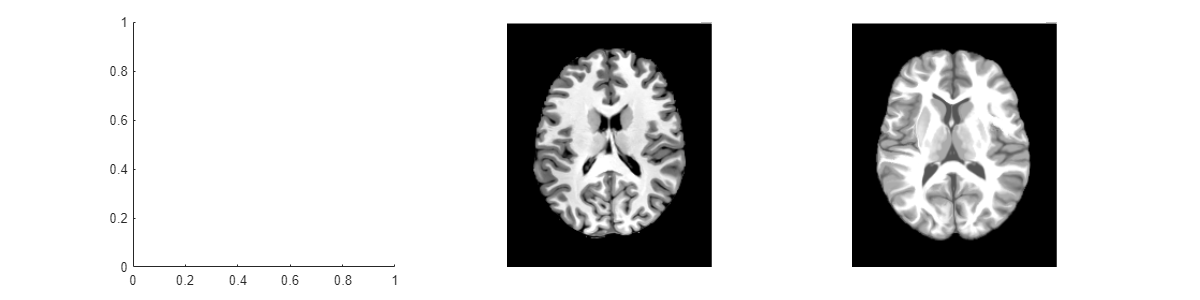


figure;
next; next; plot_mri({mri,mri_surfreg},'z','pos',[],'cross_width',0,'enhance',@amp)
lay_fig([12,3])

temp = 100*mat_cut(mri_surfreg.data-1,0);

无法解析名称 'mri_surfreg.data'。

tic
[sReg,trans_params,def_field] = MRI_register(temp,sFix,'demons','iter',200,'lv',6,'smooth_lv',1);
disp_toc
sReg.data = 0.01*single(sReg.data);

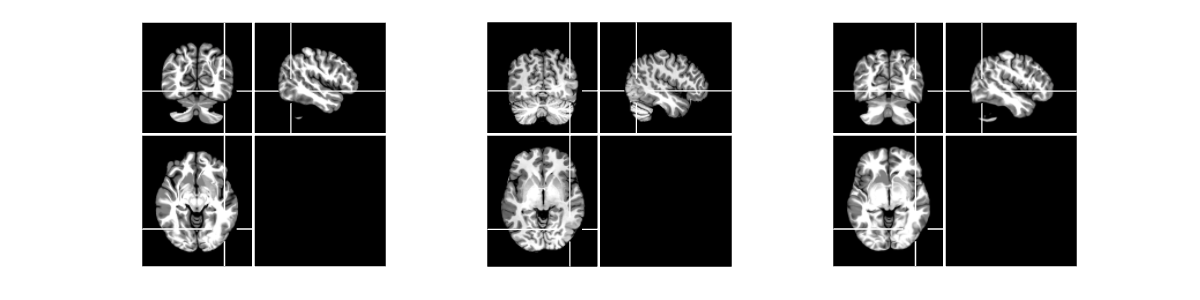

figure;
next; plot_mri({temp,sFix,sReg},'off','pos',pos,'enhance',@amp); lay_fig([12,3])

MRI_save_File(sReg.data,[compare_dir,'\T1_bstReg.nii.gz'],'info',sFix);

mri = MRI_read_Data([compare_dir,'\FEA_T1.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


mri.data = mri.data.*mat_cut(sFix.data*2,0,1);
MRI_save_File(mri.data,['D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig4\compare_reg\T1_inflatReg.nii.gz'],'info',sFix);

mri_names = {'T1_antReg','T1_elasReg','T1_demonsReg','T1_bstReg','T1.mni_reg','T1_inflatReg'};
cortex_mask = MRI_read_Data([compare_dir,'\cortex_mask.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


cortex_mask = single(cortex_mask.data);

mri_base = MRI_read_Data([compare_dir,'T1.norm_reg.nii.gz']);

sMRI [229,193,193] res:[1,1,1]



fig1 = figure; next
fig2 = figure; lay_sub(1,length(mri_names))
for i = 1:length(mri_names)
    mri = MRI_read_Data([compare_dir,mri_names{i},'.nii.gz']);
    if i==1
        mri.data = mat_cut(3*mri.data-1);
    end
    mri.data = single(mri.data);

    figure(fig1)
    next; plot_mri(mri,'z','pos',pos,'enhance',@amp);

    [score,qualityMaps] = multissim3(mri.data.*cortex_mask,mri_base.data.*cortex_mask);
    qual_vol = imresize3(qualityMaps{2},size(mri_base.data));
    qual_mean(i) = mean(qual_vol(cortex_mask>0),'all');

    A = mat_cut(1-2*abs(mri.data-1),0,1)>0;
    B = mat_cut(1-2*abs(mri_base.data-1),0,1)>0;
    A = A.*cortex_mask; B = B.*cortex_mask;
    A = A(:,1:round(end/2),:); B = B(:,1:round(end/2),:); 
    dice_GM(i) = 2*sum(A.*B,'all')/sum(A+B,'all');

    A = mat_cut(1-2*abs(mri.data-2),0,1)>0;
    B = mat_cut(1-2*abs(mri_base.data-2),0,1)>0;
    A = A.*cortex_mask; B = B.*cortex_mask;
    A = A(:,1:round(end/2),:); B = B(:,1:round(end/2),:); 
    dice_WM(i) = 2*sum(A.*B,'all')/sum(A+B,'all');

    temp = [qual_mean(i),dice_GM(i),dice_WM(i)];
    figure(fig2)
    next; h = bar(temp'); ylim([0.5,1]); title(mri_names{i})
    h.CData = lines(3); h.FaceColor = 'flat'; axis_none; box on
end

sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]
sMRI [229,193,193] res:[1,1,1]


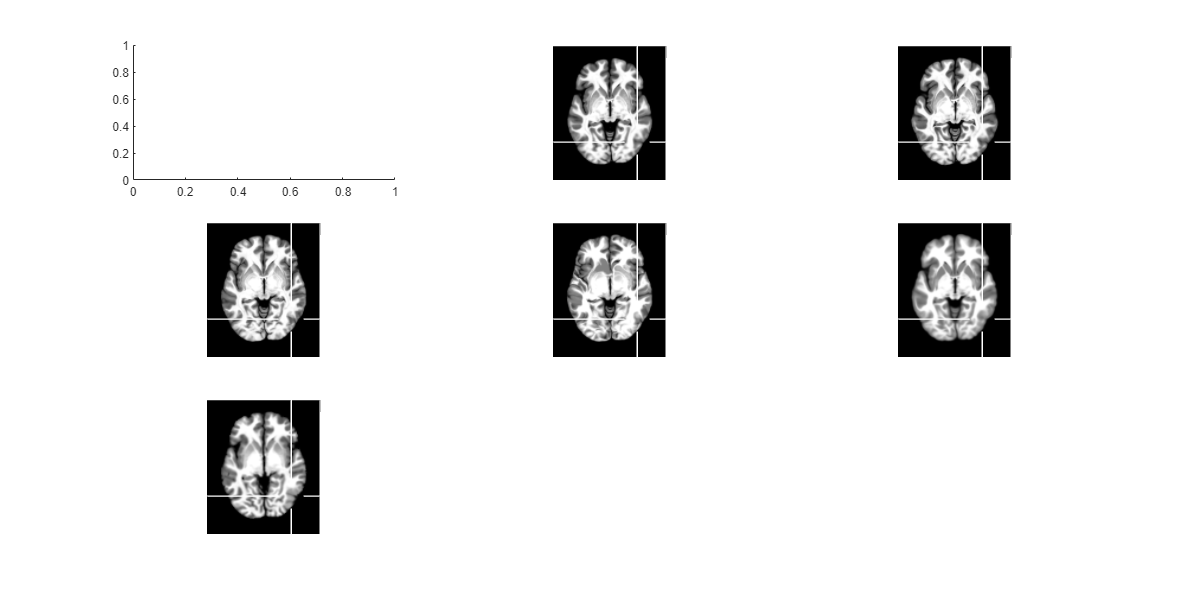

figure(fig1); lay_fig([12,6])

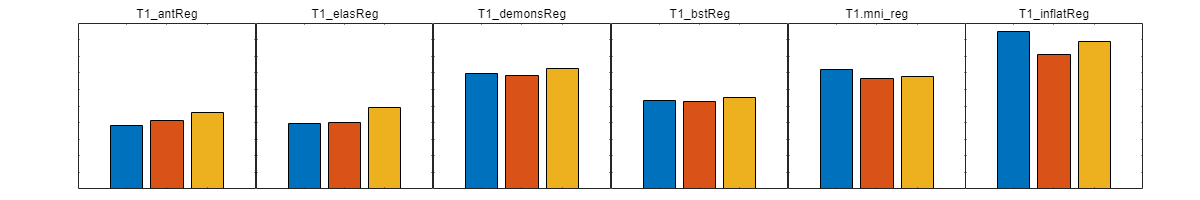

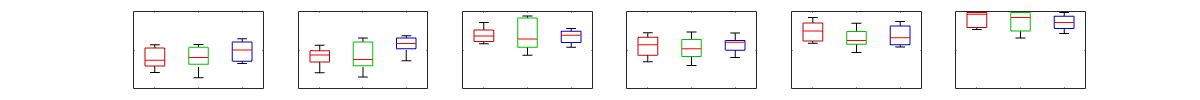

figure(fig2); lay_fig([12,2])

# deform field

def_dir = 'D:\File\work_file\Dataset\Brain\openFCD\sub-00010\reg_deffield\';

mri = MRI_read_Data([def_dir,'..\T1_rb\T1.norm_reg.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


XYZ_mniF2subj = MRI_read_Data([def_dir,'XYZ_mniF2subj.nii.gz']);

sMRI [229,193,193,3] res:[1,1,1]



T_mni2flat = MRI_read_Data(['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\XYZ_mni2flat.nii.gz']);

sMRI [229,193,193,3] res:[1,1,1]


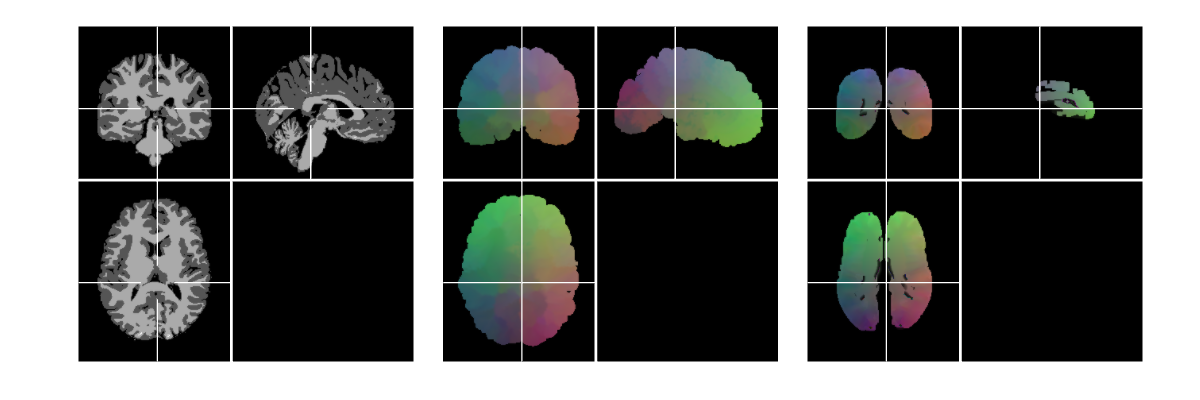

temp = [];
for i = 1:3
    temp(:,:,:,i) = imdilate(T_mni2flat.data(:,:,:,i),ones(5*[1,1,1]));
end
T_mni2flat.data(T_mni2flat.data<10) = temp(T_mni2flat.data<10);

figure; lay_sub(1,3)
next; plot_mri({mri,XYZ_mniF2subj,T_mni2flat},'off','pos',[100,100,90],'if_detrend',0); lay_fig([12,4])

T_field = [];
for i = 1:3
    temp = MRI_warp(XYZ_mniF2subj,T_mni2flat.data(:,:,:,i),'BST','interp_type',0);
    T_field(:,:,:,i) = medfilt3(mat_rmnan(temp.data),5*[1,1,1]);
end

mni_reg = MRI_warp(T_field,mni_frac,'BST');

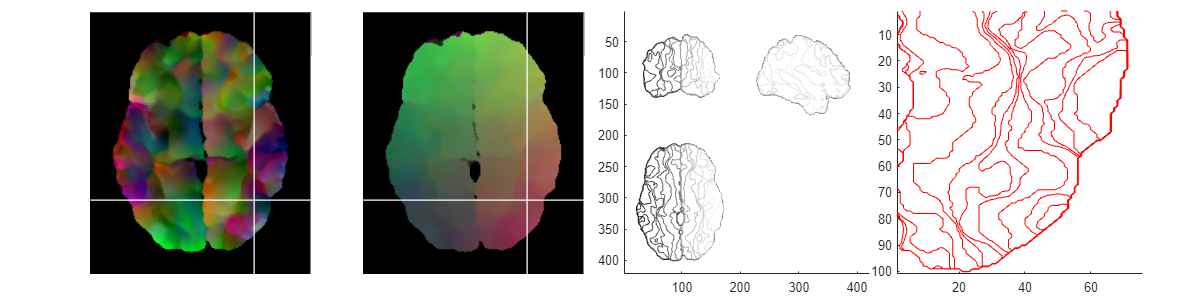

pos = [143,65,75];

figure; lay_sub(1,4)
next; img_mtg = plot_mri(T_field,'z','pos',pos,'if_detrend',1);
next; img_mtg = plot_mri(T_field,'z','pos',pos,'if_detrend',0);
img_mtg = img_mtg.*uint8(imgaussfilt(single(mean(img_mtg,3)>0),1)>0.99);
next; axis ij
for i = 1:1
    hold on; contour(img_mtg(:,:,i),20);
end
next; axis ij
x = 100:175; y = 300:400;
hold on; contour(img_mtg(y,x,1),100:5:160,'r');
% hold on; contour(img_mtg(y,x,2),30:5:120,'b');
lay_fig([12,3])

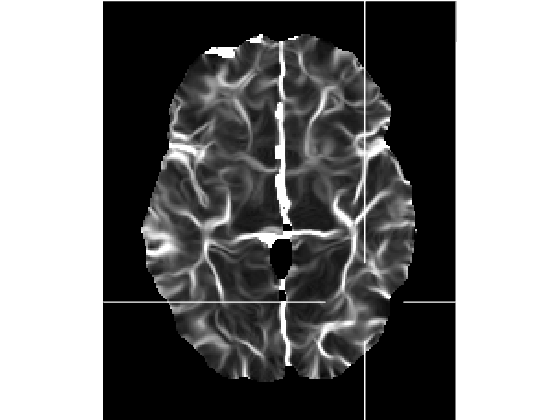

temp = mat_rmnan(T_field);
temp(temp<20) = 0;
[E1,E2,E3] = MRI_func_GEO(temp,'jacobi3_mat');

figure; next; plot_mri(amp(E1,5e-3),'z','pos',pos)

mniF_cortmask = MRI_read_Data([surfer_dir,'mniF_cortex_mask.nii.gz']);

sMRI [229,193,193] res:[1,1,1]


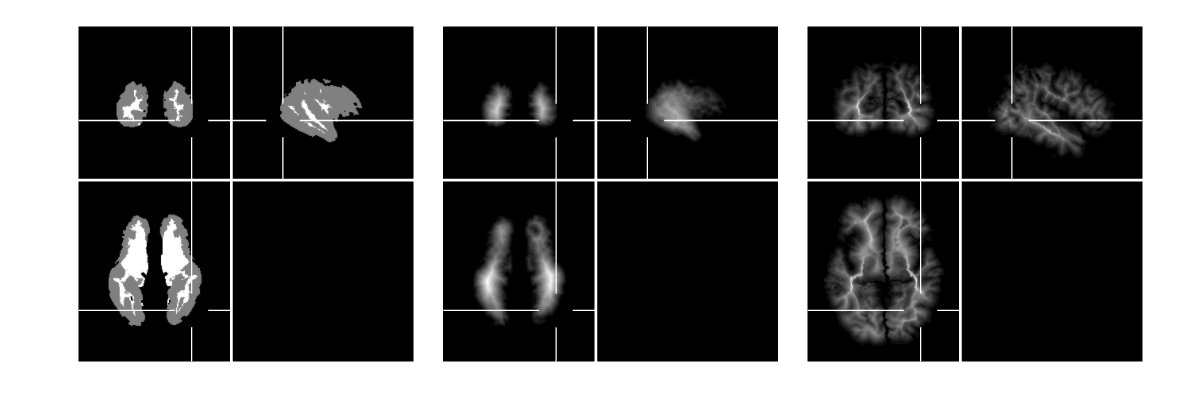

maskF_filled = imfill(mniF_cortmask.data>0,'holes');
maskF_bwdist = bwdist(~maskF_filled);
mask_bwdist = MRI_warp(XYZ_mniF2subj,maskF_bwdist);

figure; lay_sub(1,3)
next; plot_mri({mniF_cortmask,maskF_bwdist,mask_bwdist},'off','pos',pos,'if_detrend',0); lay_fig([12,4])

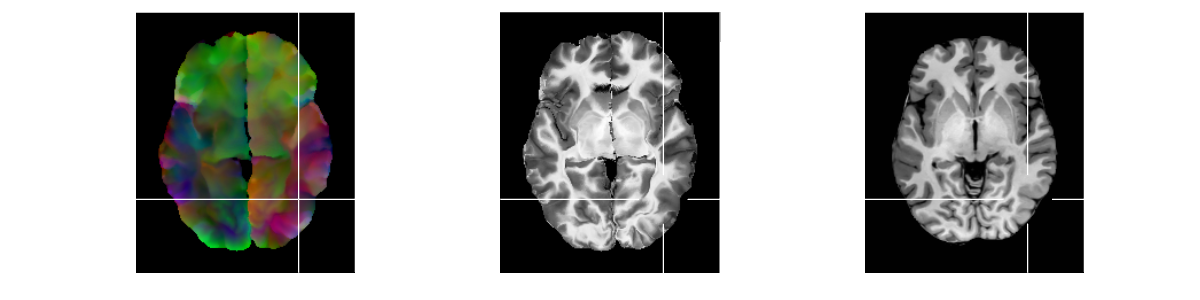

fuse_rate = mat_cut(imgaussfilt3(mat_rmnan(mask_bwdist.data)/15,0.5),0,1);
def_field_fuse = def_field_demons.*fuse_rate + T_field.*(1-fuse_rate);

sWarp = MRI_warp(def_field_fuse,sMov,'BST');

figure; lay_sub(1,3)
next; plot_mri({def_field_fuse,sWarp,sFix},'z','pos',pos,'if_detrend',1);
lay_fig([12,3])

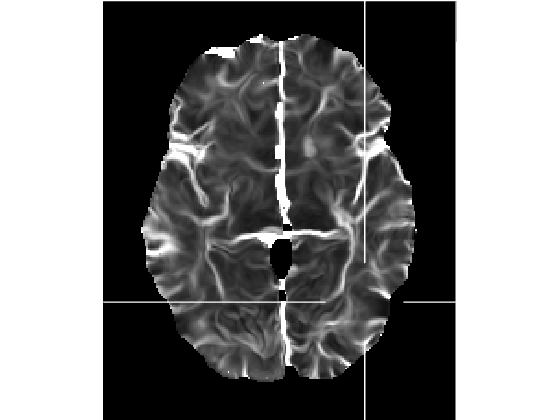

temp = mat_rmnan(def_field_fuse);
temp(temp<20) = 0;
[E1,E2,E3] = MRI_func_GEO(temp,'jacobi3_mat');

figure; next; plot_mri(amp(E1,5e-3),'z','pos',pos)

y_mri = MRI_read_Data('F:\Dataset\Brain\FCD_maps\data\patient\mri\y_sub-00010_acq-iso08_T1w.nii');

sMRI [137,113,113,3] res:[1.5,1.5,1.5]


% T1_nii = 'F:\Dataset\Brain\FCD_maps\data\patient\sub-00010_acq-iso08_T1w.nii';
% T1_mri = 
% 
% [~,Def_new] = mySPM_applyDeform(y_mri.data,T1_nii,T1_mri.data);

% Def_new = y_mri.data;
% Def_rsz = resize_field(Def_new,round(size(Def_new,1:3).*1.5));
% 
% Def_rsz = func_repos_cat12_rsz(T1frac,sFix,)
% 
% Def_rsz = Def_rsz.*(T_field(:,:,:,1)>0);

对于此运算，数组的大小不兼容。

相关文档

# volume inflat

## HCPex color nii, pial

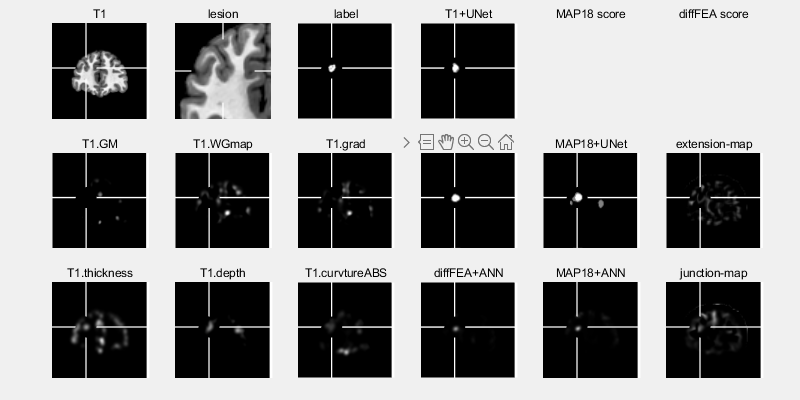

sMRI [229,193,193] res:[1,1,1]


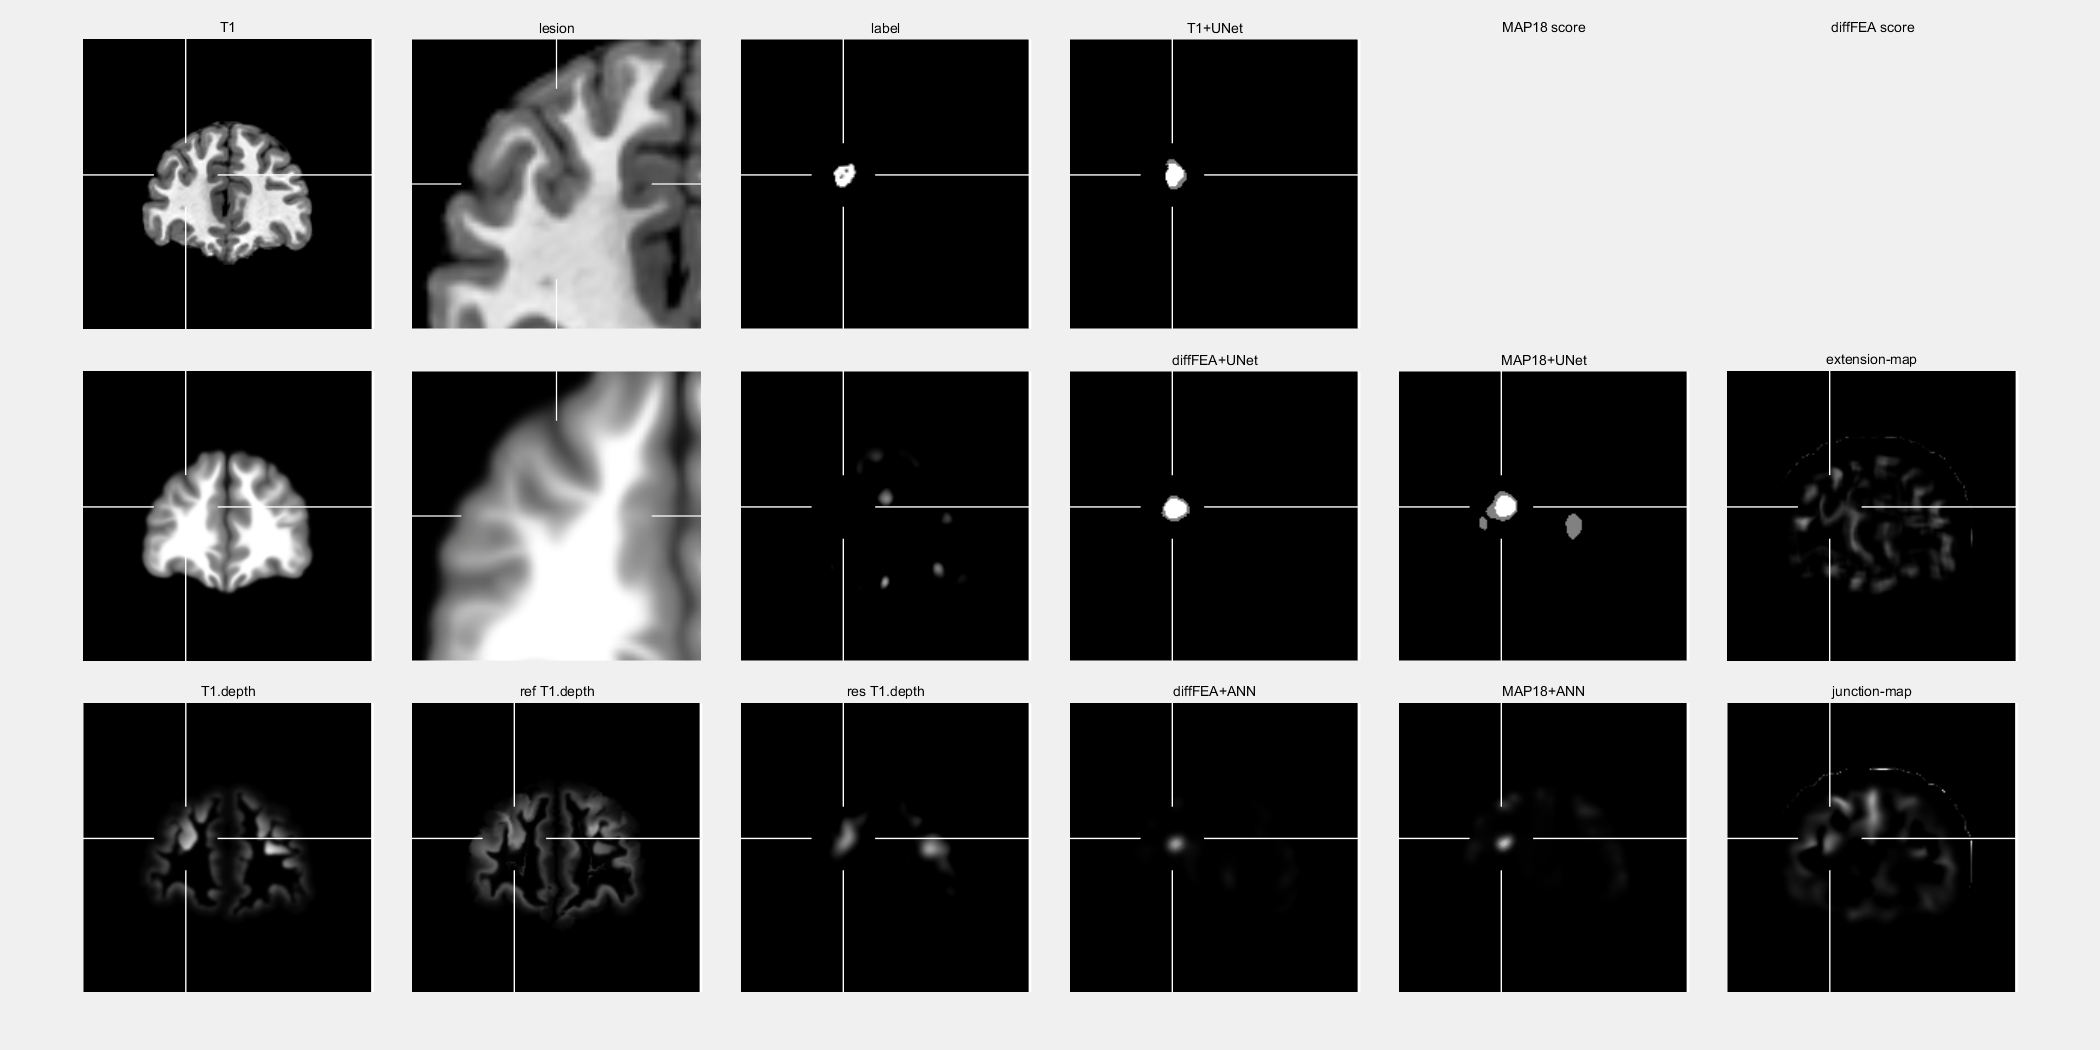

XYZ_mni2flat = MRI_read_Data(['E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\XYZ_mni2flat.nii.gz']);

XYZ_mni2flat_raw = XYZ_mni2flat;
temp = XYZ_mni2flat.data;
for i = 1:3
    temp(:,:,:,i) = imdilate(temp(:,:,:,i),ones(7*[1,1,1]));

sMRI [229,193,193,3] res:[1,1,1]


    temp(:,:,:,i) = medfilt3(temp(:,:,:,i),[1,1,1]*5);
    % temp(:,:,:,i) = medfilt3(temp(:,:,:,i),[1,1,1]*5);
    % temp(:,:,:,i) = imgaussfilt3(temp(:,:,:,i),2);
end
XYZ_mni2flat.data(XYZ_mni2flat.data<70) = temp(XYZ_mni2flat.data<70);

figure;
next; plot_mri(XYZ_mni2flat,'off')

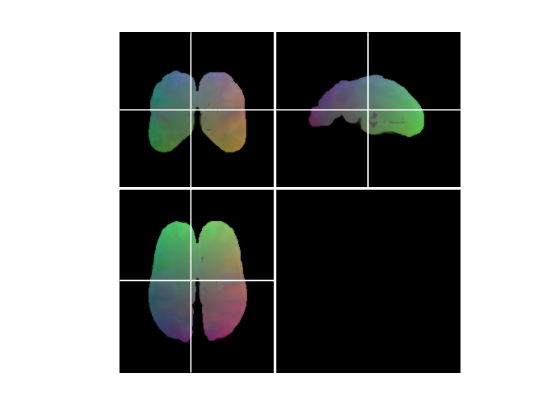

save_dir = 'D:\Doc\投稿论文\FCD\flatReg\Fig_material\Fig2\vol_inflat';
func_savenii = @(V,path,info) niftiwrite(permute(V,[2,1,3]),path,info,"Compressed",true);

info = niftiinfo('E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\HCPex.nii.gz');

HCPv = niftiread(info);
HCPv = permute(HCPv,[2,1,3]);

sMRI [229,193,193,3] res:[1,1,1]



HCPf = MRI_warp(XYZ_mni2flat,HCPv,'interp_type',0);

HCPf.data = medfilt3(mat_rmnan(HCPf.data),[1,1,1]*5);
func_savenii(HCPf.data,[save_dir,'\HCPex_inflat'],info);

V_ext = imdilate(HCPv,ones(5*[1,1,1]));
V_inn = V_ext.*(mni_frac.data>0.8);

func_savenii(V_inn,[save_dir,'\HCPex_innV'],info);

V_innf = MRI_warp(XYZ_mni2flat,V_inn,'interp_type',0);

V_innf = medfilt3(mat_rmnan(V_innf.data),[1,1,1]*5);
func_savenii(V_innf,[save_dir,'\HCPex_innF'],info);

% pos = [96,145,78];
pos = [137,147,109];
% pos = [];

figure; lay_sub(1,3)
next; img_mtg = plot_mri(XYZ_mni2flat,'z','pos',pos,'if_detrend',0);
next; def_mtg = plot_mri(XYZ_mni2flat,'z','pos',pos,'if_detrend',1);

img_mtg = img_mtg.*uint8(imgaussfilt(single(mean(img_mtg,3)>0),1)>0.99);
temp = imdilate(img_mtg,ones(5*[1,1]));
img_mtg(temp<200) = temp(temp<200);

next; axis ij
showc(def_mtg)
for i = [1,2]
    hold on; contour(img_mtg(:,:,i),20,'Color',[1,1,1],'LineWidth',1);
end
lay_fig([12,4])

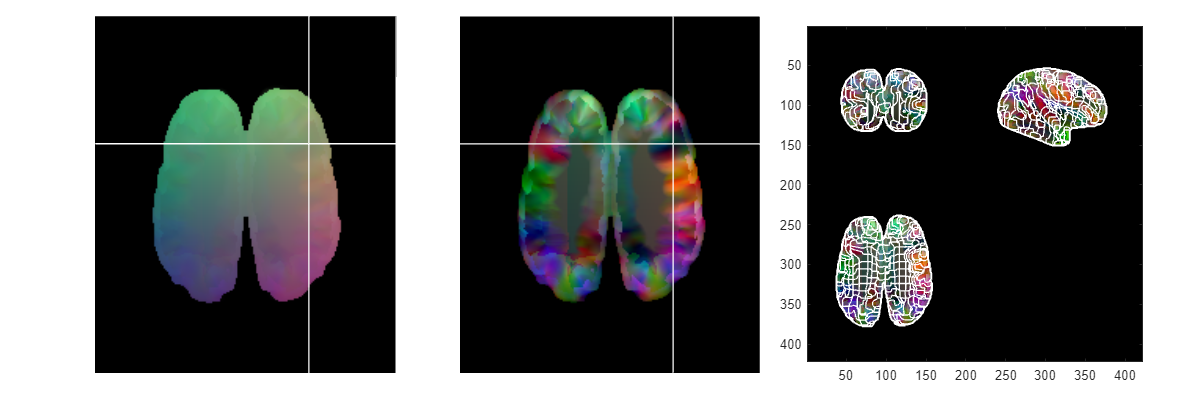

temp = XYZ_mni2flat.data;
sz = size(temp);
[X,Y,Z] = meshgrid(1:sz(2),1:sz(1),1:sz(3));
temp = temp - cat(4,X,Y,Z);

for i = 1:3

    temp(:,:,:,i) = imgaussfilt3(temp(:,:,:,i),1*[1,1,1]);
end

XYZ_det = spm_diffeo('def2det',temp);
mask = (mean(XYZ_mni2flat_raw.data,4)>10);
XYZ_det = XYZ_det.*mask;

cmap_sign = jetw(255,'half');
cmap_sign_ = 1 - flipud(cmap_sign);
% cmap_sign_(round(end/2)+[-2:2],:) = 0;
cut_thresh = 5;
plot_mri(1+mat_cut(XYZ_det,-cut_thresh,cut_thresh))
colormap(cmap_sign_); clim(1+[-1,1]*cut_thresh)

% [E1,E2,E3] = MRI_func_GEO(XYZ_mni2flat.data,'jacobi3_mat');
XYZ_det = MRI_func_GEO(XYZ_mni2flat.data,'jacobi3_det');
XYZ_det = imgaussfilt3(XYZ_det.*mask,1);

plot_mri(1+mat_cut(XYZ_det,-cut_thresh,cut_thresh))
colormap(cmap_sign_); clim(1+[-1,1]*cut_thresh)

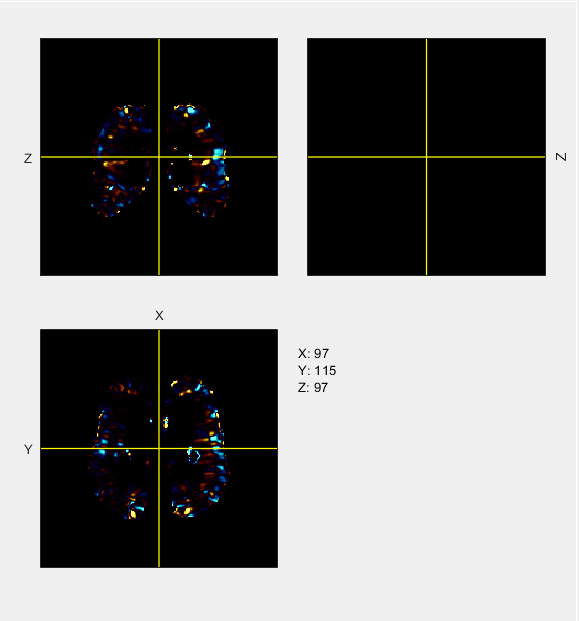

temp = mat_cut(XYZ_det,-0.1,0.1,'invert',1);

XYZ_det_ = XYZ_det.*(mask==0) + temp.*(mask==1);

plot_mri(1+mat_cut(XYZ_det_,-cut_thresh,cut_thresh))
colormap(cmap_sign); clim(1+[-1,1]*cut_thresh)

plot deform field of elastix

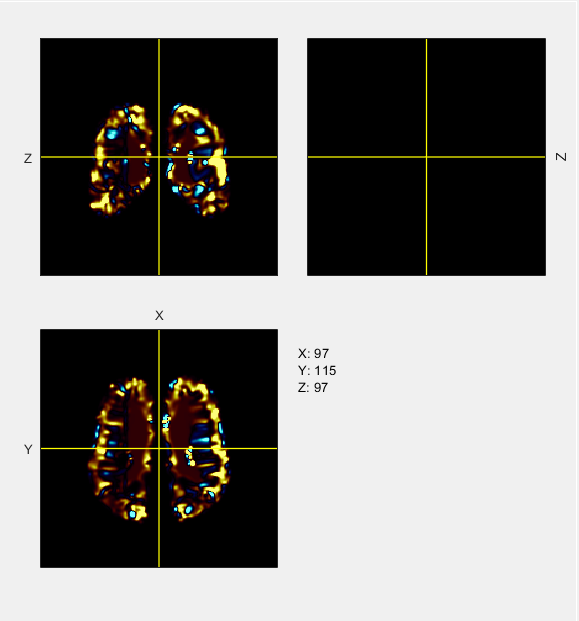

elas_map = MRI_read_Data("D:\File\work_file\Dataset\Brain\openFCD\sub-00003\T1_rb\sub2mni.map.nii.gz");
mni_norm = MRI_read_Data("E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\mni.norm.nii.gz");


elas_map.data = maskCutoff_dim4(elas_map.data, mni_norm.data>0.01, 0.1);

figure; 
next; plot_mri(elas_map.data/255,'off','if_detrend',0,'if_contour',8,'cross_width',0)

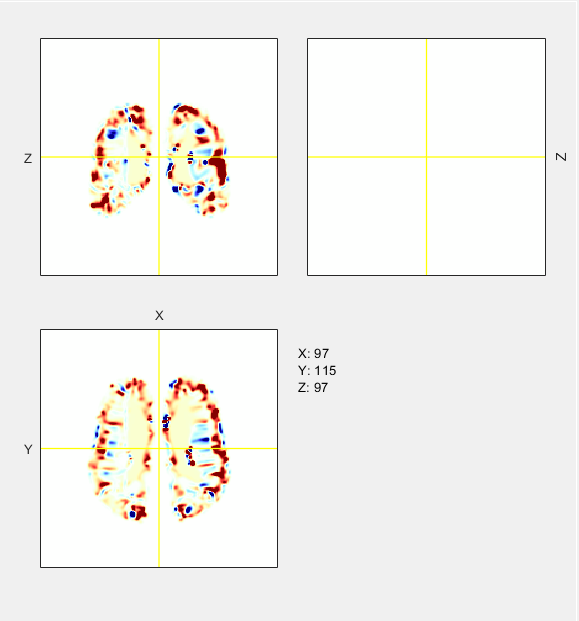

mri = MRI_read_Data('D:\File\work_file\Dataset\Brain\openFCD\sub-00003\T1_rb\T1.reg.norm.nii.gz');


reg_iter = 100;
reg_box = [20,18,15;210,178,165]';

sMRI [229,193,193,3] res:[1,1,1]


tic

sMRI [229,193,193] res:[1,1,1]


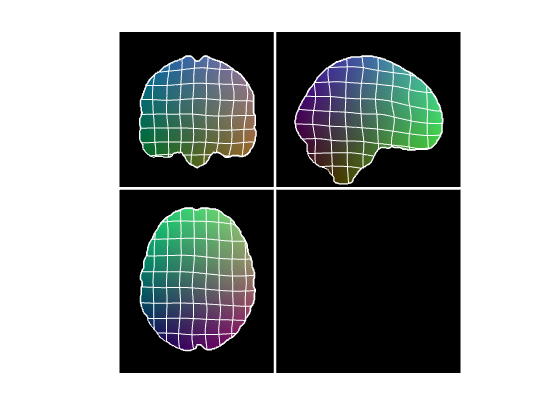

[mri_reg,D,demons_map] = imreg_demons(mni_norm.data,mri.data,reg_iter,reg_box,3,1);
toc

figure; lay_fig([12,4])
next; plot_mri({mni_norm,mri_reg},'off'); next; plot_mri(demons_map/200,'off','if_detrend',0,'if_contour',15)

MAP_linear = get_linear_field(mni_norm.data);

sMRI [229,193,193] res:[1,1,1]


MAP_fuse = 2*(elas_map.data - MAP_linear + (demons_map - MAP_linear)) + MAP_linear;
MAP_fuse = MAP_fuse.*(mni_norm.data>0);

figure;
next; plot_mri(MAP_fuse/200,'off','if_detrend',0,'if_contour',20,'cross_width',0)

function numbers = getFloat_byOCR(img,roi,verbose)

历时 8.376662 秒。


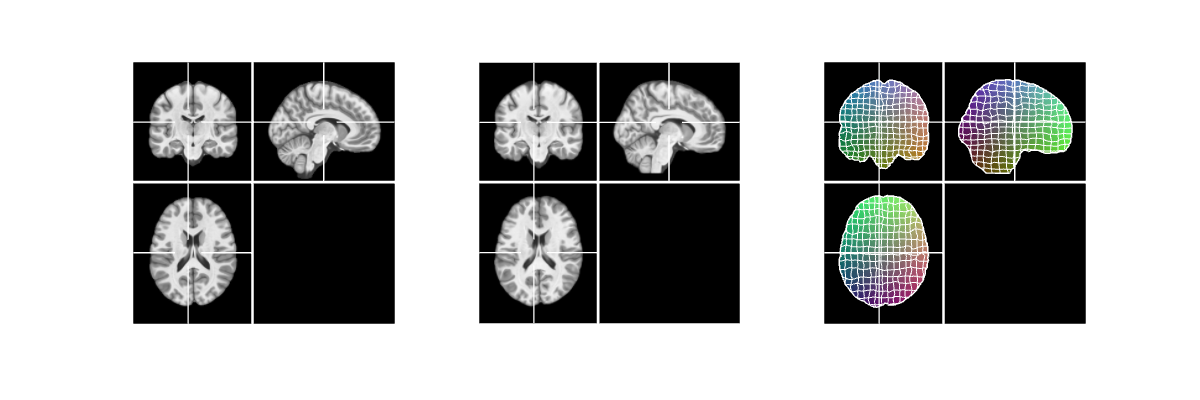

ocrResults = ocr(img,roi);
text = strtrim(ocrResults.Text);


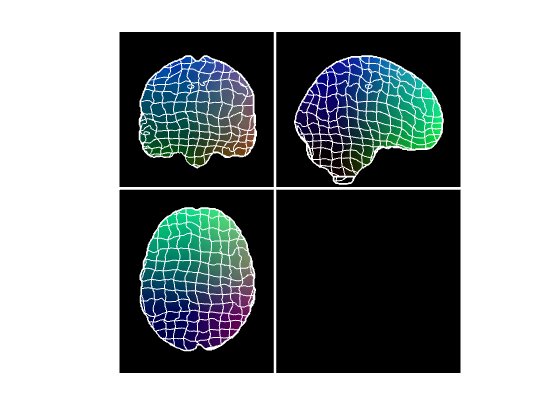

if verbose
    disp(text)
end

pattern = '\d+\.\d+';
numbers = regexp(text, pattern, 'match');
numbers = str2double(numbers);

end

function lab_cen = get_bwcen(fea_lab)
temp = regionprops3(fea_lab>0,'BoundingBox');
temp = temp.BoundingBox;
lab_cen = temp(1:3)+temp(4:6)/2;
end

function Yrsz = resize_field(Y,new_sz)
Yrsz = zeros([new_sz,3]);
for i = 1:3
    Yrsz(:,:,:,i) = imresize3(Y(:,:,:,i),new_sz);
end
end

function x = func_repos_cat12_rsz(x,ref,data)
x.data = data;
x = MRI_func_ROI(x,'repos',ref);
end

function df = maskCutoff_dim4(df, mask, percent)
for i = 1:3
    temp = df(:,:,:,i);
    temp = prctile(temp(mask),percent);
    df(:,:,:,i) = df(:,:,:,i) - temp;
end
df(df<0) = 0;
df = df.*mask;
end

function MAP = get_linear_field(ref)
[X,Y,Z] = meshgrid(1:size(ref,2),1:size(ref,1),1:size(ref,3));
MAP = cat(4,X,Y,Z).*(ref>0.01);
end

function [moving_warp,D,MAP] = imreg_demons(Im0,If0,reg_iter,box,res,sm)
Im = Im0(box(1):box(4),box(2):box(5),box(3):box(6));
If = If0(box(1):box(4),box(2):box(5),box(3):box(6));

[D,moving_reg] = imregdemons(gpuArray(Im),gpuArray(If),reg_iter,'PyramidLevels',res,'AccumulatedFieldSmoothing',sm);

moving_warp = 0*If0;
moving_warp(box(1):box(4),box(2):box(5),box(3):box(6)) = gather(moving_reg);

[X,Y,Z] = meshgrid(1:size(D,2),1:size(D,1),1:size(D,3));
MAP = repmat(0*If0,1,1,1,3);
MAP(box(1):box(4),box(2):box(5),box(3):box(6),:) = (D + cat(4,X,Y,Z)).*(If>0.01);
end